# Project

Cory Puckett

## Select Orbit

All of the halo orbits from NASA Jet Propulsion Lab (JPL)'s Solar System Dynamics (SSD) Three body periodic halo orbits are available to choose from.

Please select an orbit family and Lagrange Point or Resonace is applicable. The families available are:

- L1, L2, L3 Lyapunov orbits

- L1, L2, L3 northern Halo orbits

- L1, L2, L3, L4, L5 Vertical orbits

- L1, L2, L3, L4, L5  Axial orbits

- L4, L5 Long Period orbits

- L4, L5 Short Period orbits

- Northern Butterfly orbits

- Northern Dragonfly orbits

- Distant Retrograde orbits

- Distant Prograde orbits

- Eastern Low Prograde orbits

- Resonant orbits 

clearvars;

%Reads each of the ephemerides files
Horizon_read;

clearvars Lp res;
familys = ["Lyapunov", "Northern Halo", "Vertical", "Axial", "Long", "Short", "Northern Butterfly", ...
    "Northern Dragonfly", "Distant Retrograde", "Distant Prograde", "Eastern Low Prograde", "Resonant"];
family = familys(2);
if any(family == familys(1:2))
    lmin = 1;
    lmax = 3;
elseif any(family == familys(3:4))
    lmin = 1;
    lmax = 5;
elseif any(family == familys(5:6))
    lmin = 4;
    lmax = 5;
end

%Setting Lagrange point
if any(family == familys(1:6))
    Lp = 2; %This is the lagrange point that the user selects
else
    Lp = 0;
end

%Setting resonance
ratios = ["1,1","1,2","1,3","1,4", ...
    "2,1","2,3", ...
    "3,1","3,2","3,4", ...
    "4,1","4,3"];
if family == familys(12)
    res = ratios(1);
else
    res = "";
end
%Displaying Quantities about each orbit
% Values in table given in the following units
% Id 	x0 (LU) 	y0 (LU) 	z0 (LU) 	vx0 (LU/TU) 	vy0 (LU/TU) 	vz0 (LU/TU)
% Jacobi constant (LU2/TU2) 	Period (TU) 	Period (days) 	Stability index  	Mass ratio
if Lp ~= 0
    filename = family + " L" + Lp + ".xlsx";
elseif res ~= ""
    filename = family + " " + res + ".xlsx";
else
    filename = family + ".xlsx";
end
orbits = readtable(filename);

Please select the ID of the orbit that you wish to see propogated.

%Checking if orbit num will work for each lagrange point
disp("Please pick a number between 1 and " + size(orbits,1) + ".");

Please pick a number between 1 and 1535.


orbitid = round(748); %This is the orbit ID that the user is selecting

Or let a random one be choosen.

rando = false;
if rando
    orbitid = round(rand*size(orbits,1));
end

%Constants to use
%These are used by SSD to normalize several of the values
LU = 389703; %Length Unit
TU = 382981; %Time unit

%Finds table row for selected orbit
orbit = orbits(orbitid,:);

Here is some information about the orbit that you selected.

outstring = "The Family name is: " + filename + " \n" + ...
    "The period of this orbit is " + orbit.Period_days + " days. \n" + ...
    "The stability index is " + orbit.StabilityIndex + ". \n" + ...
    "The Jacobi Constant is " + (orbit.JacobiConstant*(LU^2/TU^2)) + " km^2/s^2. \n" + ...
    "The orbit ID is " + orbitid;
fprintf(outstring);

The Family name is: Northern Halo L2.xlsx 
The period of this orbit is 6.0607 days. 
The stability index is 1. 
The Jacobi Constant is 3.167 km^2/s^2. 
The orbit ID is 748

Now please choose a start date for the propogation of the orbit. Please pick a date between January 1 2000 and December 31 2029. September 15 2027 should result in some of the more realistic results because that is when the Sun is closest to the X axis and it is a full moon, so the Sun, Earth, and Moon are all really near the X axis at the start as is assumed in the solar perturbations.

syear = 2027;
if syear < 2000 || syear > 2030
    disp("Please choose a year between 2000 and 2030");
end
smonth = 9;
if smonth < 1 || smonth > 12
    disp("Please choose a valid month number");
end
sday = 15;
if sday < 1 || sday > 31
    disp("Please choose a valid day number");
end
global sdate;
sdate = datetime(syear,smonth,sday); %Start date
edate = sdate + duration(24*orbit.Period_days*4,0,0); %End date

The unperturbed orbit.

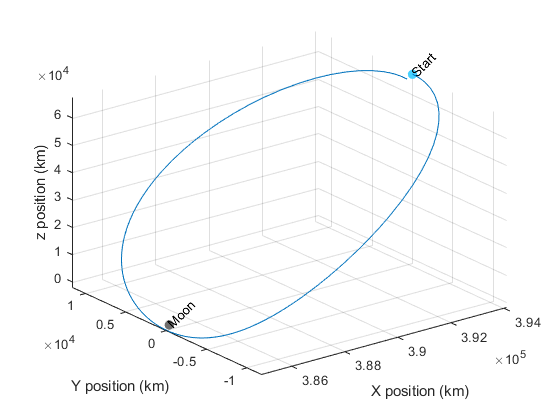

CR3BP;

figure;

% r2 = sqrt((xm(:,1)-x2).^2 + xm(:,3).^2 + xm(:,3).^2);
% disp("The minimum distance from the moon is " + min(r2) + " km.");
% disp("The minimum altitude above the moon is " + (min(r2)-1737.1) + " km.");
% r1 = sqrt((xm(:,1)-x1).^2 + xm(:,3).^2 + xm(:,3).^2);
% disp("The minimum distance from the Earth is " + min(r1) + " km.");
% disp("The minimum altitude above the Earth is " + (min(r1)-6378) + " km.");

Orbit with the addition of Solar gravitational effects.

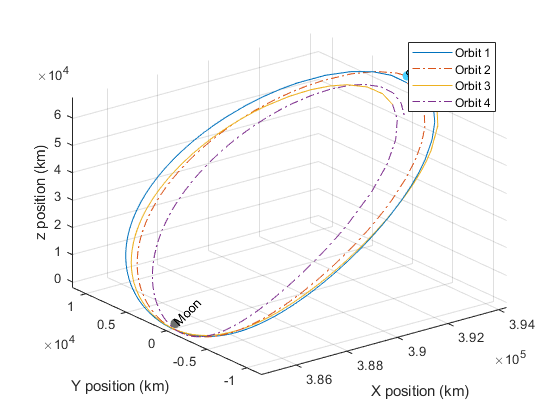

Sol_Perturb;